## Grobner Basis

Polynomial Division:

- Leading monomial: Monomial of the polynomial with the highest degree.

- Leading coefficient: Coefficient of the leading monomial.

- Leading term: Product of *a* and *b*.

- Degree of polynomial: Degree of the leading term.

- *Degree of remainder always lesser than that of the divisor.*

Monimial Orderings:

- Lexicographic ordering or Lex ordering: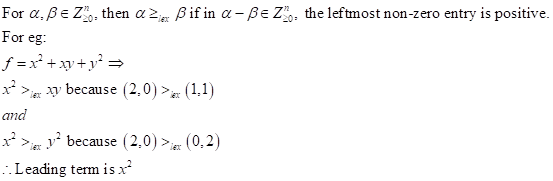

- Graded lexicographic ordering:

               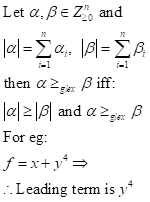

Multi-variate Polynomial Division:

- Dividing 2 polynomials:

              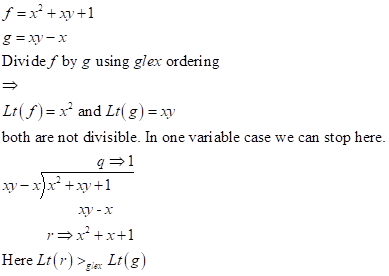

syms x y
f = x^2+x*y+1;
d = x*y-x;
[r,q] = polynomialReduce(f,d)

$$r = x^{2}+x+1$$

$$q = 1$$

- Dividing by a system of polynomials: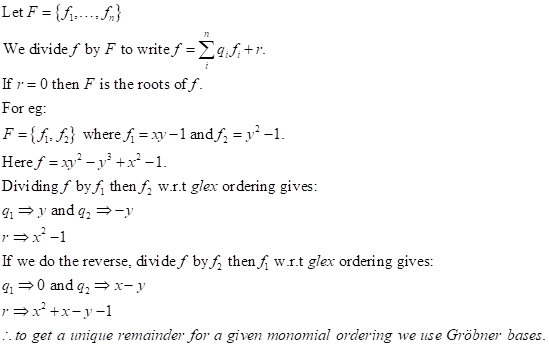

syms x y
f = x*y^2-y^3+x^2-1;
d1 = [x*y - 1, y^2 - 1];
d2 = [y^2 - 1, x*y - 1];
[r1,q1] = polynomialReduce(f,d1) %#ok<*ASGLU> 

$$r1 = x^{2}-1$$

$$q1 = \left(\begin{array}{cc} y & -y \end{array}\right)$$

[r2,q2] = polynomialReduce(f,d2)

$$r2 = x^{2}+x-y-1$$

$$q2 = \left(\begin{array}{cc} x-y & 0 \end{array}\right)$$

Rings: A ring is a non-empty set equipped with 2 operations that satisfy the following axioms:

- It is closed under addition: $if \ a \in R \ and \ b \in R \ then \ a+b \in R$

- Associative

- Commutative

- Should have additive identity: $i.e \ 0_R \in a \ such\ that\ a+0_R=a=0_R+a \  \forall a \in R$

- Should have additive inverse.

- Closed under multiplication:$if\ a \in R\ and\ b\in R\ then\ a\bullet b \in R$

- Distributive and assosiative.

- *A set of ****Z****, ****Q**** and ****C**** are rings. Set of even numbers form a ring but set of odd nos don’t.*

Field:

- A subring *I* of a ring *R* is an **ideal** *iff *when* r **∈** R *and*a **∈ I, *then* r.a **∈** I *and *a.r **∈ I*. For eg. a set of even integers is an ideal of the ring ***Z*** and $\{0_R\}$ and ***R*** are ideals for every ring ***R***.

             

- The zero ideal is generated by a single element set; *I=<0**R**>={0**R**} **∀*ring ***R***.

- Ideals can have different set of generators.

- Noetherian Rings: A ring ***R*** is a Noetherian ring if every ideal *I* of ***R*** is finitely generated. And, according to Hilbert’s Basis Theorem if *R* is a Noetherian ring then so is the polynomial ring *R[x]*.

Gröbner Basis: (LM(*f*) denotes fixed monomial ordering and LT(*f*) denotes the leading term.)

- A Gröbner basis of an ideal *I* is a set of generators of *I*.

- For a fixed monomial ordering a finite subset *G=*$\{g_1,...,g_t\}$ of an ideal *I* is said to be a Gröbner basis if:$<LT(g_1),...,LT(g_t)>=<LT(I)>$

- Reduced Gröbner basis: A RGb for a set of polynomials *F* is a Gröbner basis *G*of *F* such that: 1. LC is 1 $\forall p \in G$ and for all $p \in G$, none of the terms of *p* is divisible by the $LT(q) \ \forall \ q \in G-\{p\}$

- S-polynomials: 

             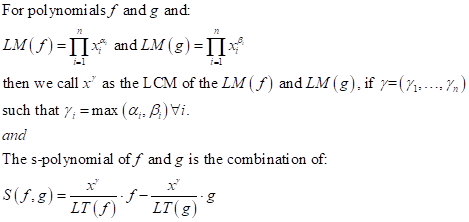

- For example:

             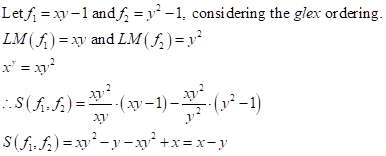

Buchberger's Algorithm:

- Chose the monomial ordering.

- Start with *G := F*.

- Repeat G’ := G until G = G’

              For example:

             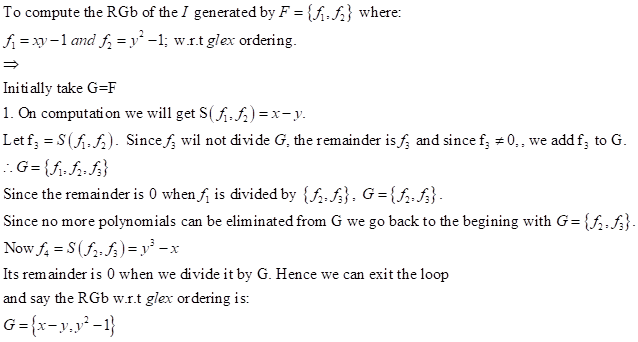

syms x y
r = [x*y-1, y^2-1];
G = gbasis(r)

$$G = \left(\begin{array}{cc} y^{2}-1 & x-y \end{array}\right)$$

Unique Remainders:

- For example:

            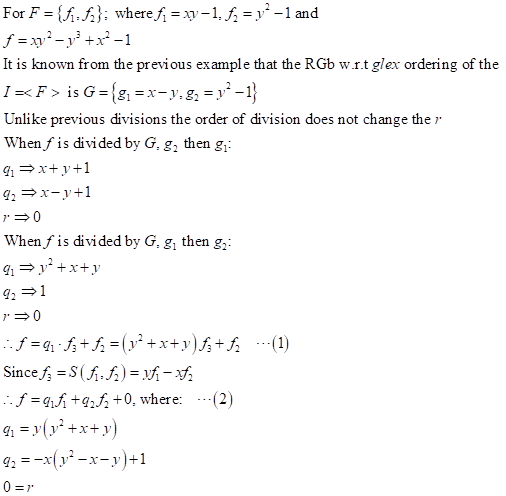

syms x y
f = x*y^2-y^3+x^2-1;
d = [x*y-1,y^2-1];
G = gbasis(d);
Gd = [G(1,2) G(1,1)];
[r1,q1] = polynomialReduce(f,G)

$$r1 = 0$$

$$q1 = \left(\begin{array}{cc} x-y+1 & x+y+1 \end{array}\right)$$

[r2,q2] = polynomialReduce(f,Gd)

$$r2 = 0$$

$$q2 = \left(\begin{array}{cc} y^{2}+y+x & 1 \end{array}\right)$$

        A zero remainder implies that the solutions of *F* are the roots of *f*. In conclusion, to divide a polynomial *f* by                  a set of polynomials *F* to get a unique remainder the following steps are to be followed:

- Compute Gröbner basis $G=\{g_1,...,g_t\}$ of the ideal *I=<F>.*

- Divide *f* by *G *to get a unique remainder *r*.

- Trace the quotients$q_i,\ i=1\ to\ n$ from the S-polynomials to write $f=q_1f_1+...+q_nf_n+r$